PROYECTO 3. S&S SEÑALES Y SISTEMAS. PARTE 1.

Variables Iniciales Generales

n_bits=16; %bits por muestra
fs=16000; %frecuencia HZ
n_channels=1;%canal 
Td=2;        %tiempo de grabacion 2seg

Punto 1) Grabación y almacenamiento de audios 

Letra A

%Ingrese opcion para grabar los audios:
%AUDIO 1
avisoA1= input('Presione la letra "s" para iniciar la primera grabación: ','s' );
if avisoA1=='s' 
   LetraA1=audiorecorder( fs,n_bits,n_channels,-1); %creacion del objeto
   disp('inicia grabacion 1 (2 segundos)');
   recordblocking(LetraA1,Td); %Grabar voz
   disp('fin de grabacion 1');
   LetraA_t1=getaudiodata(LetraA1);%almacenamiento de datos del arreglo
   audiowrite('carpeta A/Letra A_1.wav',LetraA_t1, fs);%guardar audio en carpeta
end

inicia grabacion 1 (2 segundos)


fin de grabacion 1



%AUDIO 2
avisoA2= input('Presione la letra "s" para iniciar la segunda grabación: ','s' );
if avisoA2=='s' %Grabar voz
    LetraA2=audiorecorder(fs,n_bits,n_channels,-1);
    disp('inicia grabacion 2 (2 segundos)');
    recordblocking(LetraA2,Td);
    disp('Fin de grabacion 2');
    LetraA_t2=getaudiodata(LetraA2);
    audiowrite('carpeta A/Letra A_2.wav',LetraA_t2, fs);
end

inicia grabacion 2 (2 segundos)


Fin de grabacion 2



%AUDIO 3
avisoA3= input('Presione la letra "s" para iniciar la tercera grabación: ','s' );
if avisoA3=='s' %Grabar voz
    LetraA3=audiorecorder(fs,n_bits,n_channels,-1);
    disp('inicia grabacion 3 (2 segundos)')
    recordblocking(LetraA3,Td);
    disp('Fin de grabacion 3');
    LetraA_t3=getaudiodata(LetraA3);
    audiowrite('carpeta A/Letra A_3.wav',LetraA_t3, fs);
end

inicia grabacion 3 (2 segundos)


Fin de grabacion 3


Punto 2) Carga, información, visualización de gráficas y reproducción de audios

    %Cargar audios
    [LetraA_t1, fs]=audioread('carpeta A/Letra A_1.wav');
    [LetraA_t2, fs]=audioread('carpeta A/Letra A_2.wav');
    [LetraA_t3, fs]=audioread('carpeta A/Letra A_3.wav');
    
    %Informacion general de las señales de audio
    Ts=1/fs;    %frecuencia de muestreo         
    N=length(LetraA_t2); %Numero de muestras    
    Td=N*Ts;             %duracion
    t=[0:Ts:Td-Ts];      %tiempo de grafica

    %la misma duracion, frecuencia de muestreo, bits y canales son usados en los 3 audios.
    fprintf('----------------Información General-----------------');

----------------Información General-----------------

    fprintf('La duracion de las señales es de: %6.1f', Td);

La duracion de las señales es de:    2.0

    fprintf('La frecuencia de muestreo de las señales es de: %6.1f', fs);

La frecuencia de muestreo de las señales es de: 16000.0

    fprintf('El número de muestras N de las señales es de: %6.1f', N);

El número de muestras N de las señales es de: 32000.0

    fprintf('El número de bits por muestra de las señales es de: %6.1f', n_bits);

El número de bits por muestra de las señales es de:   16.0

    fprintf('El número de canales de las señales es: %6.1f', n_channels);

El número de canales de las señales es:    1.0


    %Gráficas en tiempo:
    fprintf('-----------Gráficas en tiempo-----------------------');

-----------Gráficas en tiempo-----------------------

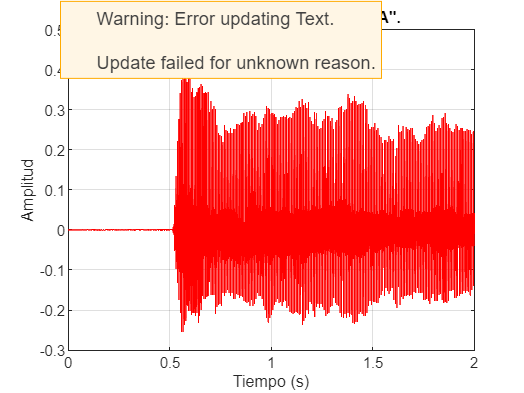

        %AUDIO 1
    plot(t ,LetraA_t1, 'r-'), grid on             %funcion para mostrar señal 
    title(['Señal en tiempo 1 de la vocal "A".']);
    xlabel(['Tiempo (s)']);
    ylabel('Amplitud');
    ax = gca; ax.FontSize = 8;  %ajuste de tamaño de fuentes 

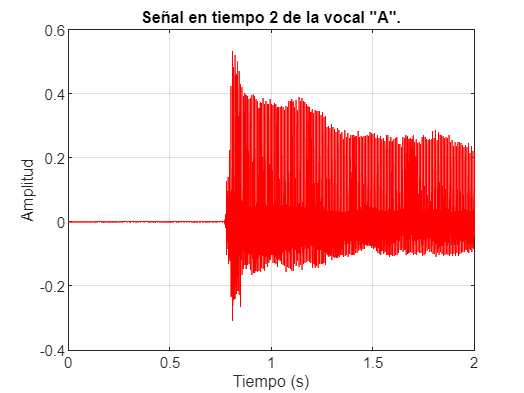

        %AUDIO 2
    plot(t ,LetraA_t2, 'r-'), grid on
    title(['Señal en tiempo 2 de la vocal "A".']);
    xlabel(['Tiempo (s)']);
    ylabel('Amplitud');
    ax = gca; ax.FontSize = 8;

        %AUDIO 3
    plot(t ,LetraA_t3, 'r-'), grid on
    title(['Señal en tiempo 3 de la vocal "A".']);
    xlabel(['Tiempo (s)']);
    ylabel('Amplitud');
    ax = gca; ax.FontSize = 8;
    
    %Reproducción de audios
    fprintf('-------------Reproducción de audios------------------');

-------------Reproducción de audios------------------

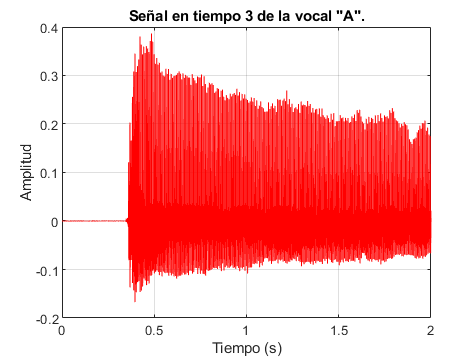

    pause(4);

    disp('Reproduciendo audio A1');

Reproduciendo audio A1


    play(LetraA1);
    pause(4);
    disp('Reproduciendo audio A2');

Reproduciendo audio A2


    play(LetraA2);
    pause(4);
    disp('Reproduciendo audio A3');

Reproduciendo audio A3


    play(LetraA3);

Punto 3) Energía, Transformada de Fourier 

    % Energía total señal 
    fprintf('-----------Energía de las señales--------------------');

-----------Energía de las señales--------------------

    abs_EA1=(abs(LetraA_t1)).^2;  %potencia promedio de señal discreta 
    abs_EA2=(abs(LetraA_t2)).^2;
    abs_EA3=(abs(LetraA_t3)).^2;

    Energy_A1=sum(abs_EA1,"all"); %sumatoria de potencia =ENERGIA 
    Energy_A2=sum(abs_EA2,"all");
    Energy_A3=sum(abs_EA3,"all");
    fprintf('La energía en la señal A-1 es: %6.1f', Energy_A1);

La energía en la señal A-1 es:  101.8

    fprintf('La energía en la señal A-2 es: %6.1f', Energy_A2);

La energía en la señal A-2 es:  638.8

    fprintf('La energía en la señal A-3 es: %6.1f', Energy_A3);

La energía en la señal A-3 es: 1086.7


    %FFT-Gráficas
    deltaf=1/Td; %resolucion de frecuencia;
    f=[0:deltaf:fs-deltaf]; %tiempo de muestreo de la señal
    fprintf('-----------Gráficas en frecuencia-------------------');

-----------Gráficas en frecuencia-------------------

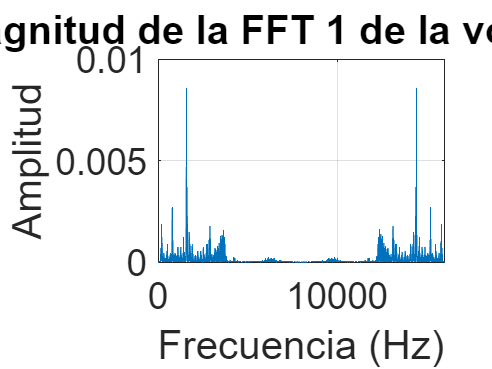

        %A1
    LetraA_f1=fft(LetraA_t1)/N; %transformada de Fourier de la señal en tiempo
    %Frec_A1db = 20*log(abs(LetraA_f1)); % magnitud en decibeles 
    plot(f, abs(LetraA_f1)), grid on    % grafica en decibeles 
    title(['Magnitud de la FFT 1 de la vocal "A".'])
    xlabel(['Frecuencia (Hz)'])
    ylabel('Amplitud')
    ax = gca; ax.FontSize = 20;   %ajuste de tamaño de fuentes 

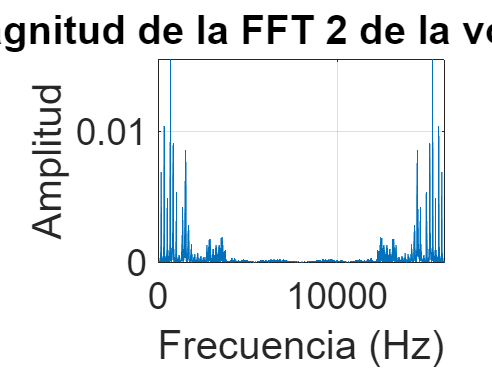


        %AUDIO 2
    LetraA_f2=fft(LetraA_t2)/N;
    %Frec_A2db = 20*log(abs(LetraA_f2));
    plot (f, abs(LetraA_f2)), grid on
    title(['Magnitud de la FFT 2 de la vocal "A".'])
    xlabel(['Frecuencia (Hz)'])
    ylabel('Amplitud')
    ax = gca; ax.FontSize = 20;

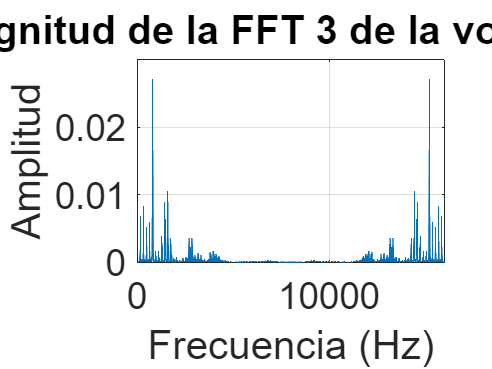


       %AUDIO 3
    LetraA_f3=fft(LetraA_t3)/N;
    %Frec_A3db = 20*log(abs(LetraA_f3));
    plot (f, abs(LetraA_f3)), grid on
    title(['Magnitud de la FFT 3 de la vocal "A".'])
    xlabel(['Frecuencia (Hz)'])
    ylabel('Amplitud')
    ax = gca; ax.FontSize = 20;


    % Porcentaje de energía de 200Hz - 1200Hz
    fprintf('--------Energía entre 200-1200 Hz-----------------');

--------Energía entre 200-1200 Hz-----------------

        %A1
    rangoA1=LetraA_f1(400:2400); %acotamiento 
    MagA1=(abs(rangoA1)).^2;     %potencia promedio 
    SumA1=sum(MagA1,"all")*N;    %sumatoria de potencia promedio=ENERGIA 
    fprintf('La energía (J) en la señal A-1 de 200 Hz a 1200 Hz es: %6.1f', SumA1);

La energía (J) en la señal A-1 de 200 Hz a 1200 Hz es:    5.6

    Porc_EA1=(SumA1/Energy_A1)*100; %valor en porcentaje
    fprintf('Su porcentaje de energía es: %6.1f', Porc_EA1); 

Su porcentaje de energía es:    5.5

        %AUDIO 2
    rangoA2=LetraA_f2(400:2400);
    MagA2=(abs(rangoA2)).^2;
    SumA2=sum(MagA2,"all")*N;
    fprintf('\nLa energía (J) en la señal A-2 de 200 Hz a 1200 Hz es: %6.1f', SumA2);


La energía (J) en la señal A-2 de 200 Hz a 1200 Hz es:  208.6

    Porc_EA2=(SumA2/Energy_A2)*100;
    fprintf('Su porcentaje de energía es: %6.1f', Porc_EA2);   

Su porcentaje de energía es:   32.7

        %AUDIO 3
    rangoA3=LetraA_f3(400:2400);
    MagA3=(abs(rangoA3)).^2;
    SumA3=sum(MagA3,"all")*N;
    fprintf('\nLa energía en la señal A-3 de 200 Hz a 1200 Hz es: %6.1f', SumA3);


La energía en la señal A-3 de 200 Hz a 1200 Hz es:  392.6

    Porc_EA3=(SumA3/Energy_A3)*100;
    fprintf('Su porcentaje de energía es: %6.1f', Porc_EA3);   

Su porcentaje de energía es:   36.1